#  Graphics in MATLAB

clear, format short g, format compact

## 2-D Graphics: `plot` function

### Single Figure

Plotting a curve is as simple as:

or, using an anonymous function,

#### Example: Wiggly Curve

First, execute the following.

f1 = @(x) cos(x).*sin(cos(tan(x)));  % line 1
x = 2*pi*[0:.0001:1];                % line 2
% or  x = linspace(0, 2*pi, 10001);  
plot(x, f1(x));                      % line 3


Observe what happens after applying the following modifications one by one.

- Change line 3 into `plot(x, f1(x), 'r')`.

- Change line 3 into `plot(x, f1(x), 'r--')`.

- After line 3, add `axis equal, axis tight`.

- Then add `text(4.6, -0.3, 'very wiggly')`.

- Then add `xlabel('x axis'), ylabel('y axis'), title('A wiggly curve')`.

Once done, save it as a png file by running:

print -dpng 'wiggly'
% or  print -djpeg 'wiggly'
% or  print -djpeg 'wiggly'

#### Exercise

Write a script to do the following:

**(a)** Define $f(x) = x^3 + x$ as an anonymous function.

**(b)** Find $f'$ and $f''$ and define them as anonymous functions.

**(c)** Plot all three functions in one figure in the interval $[-1, 1]$.

**(d)** Include labels and title in your plot.

**(e)** Add legend to the graph using, e.g `legend('f', 'fprime', 'f2prime')`.

**(f)** Save the graph as a pdf file.

% Type your answer here:
f = @(x) x.^3 + 3;
fp = @(x) 3*x.^2;
fpp = @(x) 6*x;







### Multiple Figures: Stacking

Suppose we have three sets of data:

n = 31;
x = linspace(0, 1, n+1);
y1 = x.^2; y2 = x.^4; y3 = x.^6;

To draw three curves using data (`x, y1`), (`x, y2`), and (`x, y3`) in one plotting window, we can do

Alternately, we can plot one graph, type `hold on`, and then continue to add plotting statements.

clf


#### Exercise

Expand on the previous script to produce an image shown below:

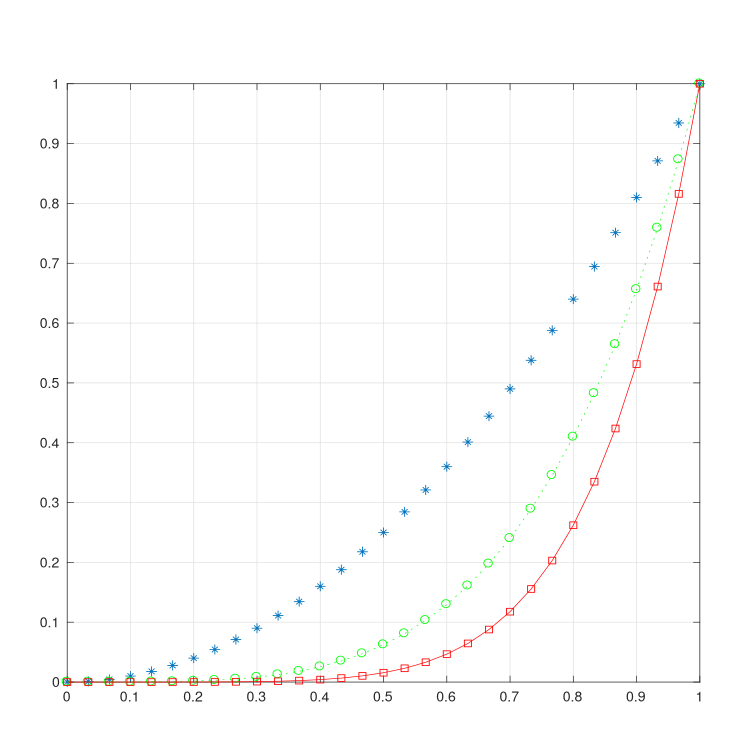

*Hint.* Type `help grid` on the command window.

% Type your answer here:




### Multiple Figures: Subplots

To draw multiple figures separately side by side, or one on top of another, use `subplot(m, n, p)`:

- it divides the current figure window into an $m \times n$ grids of smaller plots.

- $p$ determines which of the $mn$ grids is to be used. 

For example,

subplot(3, 1, 1)
plot(x, y1), grid on

subplot(3, 1, 2)
plot(x, y2, 'g'), grid on

subplot(3, 1, 3)
plot(x, y3, 'r'), grid on

## 2-D Graphics: `polar` Function

To draw the polar curve


$$r = f(\theta)$$


for $\theta \in [a, b]$, we sample $n$ points $\{ (\theta_i, r_i) \,\mid \, r_i = f(\theta_i), \; 1 \le i \le n \}$ on the curve and form vectors `th` and `r`. Then type `polar(th, r)`.

#### Example

To plot the polar function


$$r = (\cos 3\theta + 2 \cos 2\theta)^2, \qquad \theta \in [0, 2\pi]$$


we simply write

clf
theta = linspace(0, 2*pi, 361);
r = (cos(3*theta) + 2*cos(2*theta)) .^ 2;
polar(theta, r)

#### Exercise

1. Draw the graph of two-petal leaf given by


$$r = f(\theta) = 1 + \sin 2\theta, \qquad \theta \in [0, 2\pi].$$


2. Draw the graphs of of


$$r = f(\theta-\pi/4), \quad r = f(\theta-\pi/2), \quad r = f(\theta-3\pi/4)$$


on the same plotting window. Does your figure make sense?

% Type your answer here:




## 3-D Graphics: `plot3` Function

3-D curves are plotted in an analogous fashion. Namely, construct a triple of $n$-vectors `x`, `y`, and `z` corresponding to the set of data points $\{ (x_i, y_i, z_i) | i = 1, 2, \ldots, n \}$ which are in order on the curve. Then simply type:

For example, to plot the helix given by the parametrized equation


$$\mathbf{r}(t) = \langle 10 \cos(t), 10 \sin(t), t \rangle, \quad t \in [0, 10\pi],$$


t = linspace(0, 10*pi, 1000);
x = 10*cos(t); y = 10*sin(t); z = t;


#### **Exercise:**

Modify the code to generate a corkscrew by putting the helix outside of an upside down cone. (*Hint*: Parametrize a trajectory on the cone $z = x^2 + y^2$.)

% Type your answer here:



## 3-D Graphics: `surf` Function

One can also plot the surface of $z = f(x,y)$ on $R = [a, b] \times [c, d]$ using MATLAB. We will illustrate how it works via an example. 

#### **Example:** Saddle

Plot the saddle parametrized by 


$$\frac{z}{c} = \frac{x^2}{a^2} - \frac{y^2}{b^2}$$


for your choice of $a$, $b$, and $c$. 

x = linspace(-3, 3, 40);
y = linspace(-2, 2, 30);
[X, Y] = meshgrid(x, y);

clf
a = 1.5; b = 1.5; c = .5;
g2 = @(x,y) c*( x.^2 /a^2 - y.^2 /b^2);


Note that `surf` requires coordinates for a mesh grid on the domain $R$ as well as the corresponding $z$-values. `meshgrid` function is useful in generating grid coordinates. 

help meshgrid

#### Example: Oblate Spheroid

The figure for Problem 4 of Homework 1 was generated using the following code, originally from our own textbook. 

a = 1; b = 1.35; c = 1;
nr_th = 41; nr_ph = 31;
x = @(th, ph) a*cos(th).*sin(ph);
y = @(th, ph) b*sin(th).*sin(ph);
z = @(th, ph) c*cos(ph);
th = linspace(0, 2*pi, nr_th);
ph = linspace(0, pi, nr_ph);
[T, P] = meshgrid(th, ph);
surf(x(T,P), y(T,P), z(T,P))
colormap(winter)
axis equal, axis off, box off

## **Summary and Tips**

- To plot a 2-D curve:

- To plot multiple 2-D curves:

              or use `hold on `to stack in one figure window. 

              Use `subplot` to put multiple separate graphs in a single figure window. 

- To plot a 3-D curve:

- To plot a 2-D surface in 3-D:

            where `X` and `Y` are matrices of $x$- and $y$-coordinates of points in a 2-D domain and `Z` is the matrix of corresponding $z$ values. `X` and `Y` are conveniently computed using `[X, Y] = meshgrid(x, y)`.  

- To specify line properties such as colors, styles, and markers:

            For more customizing options, see Table 4.1 of the textbook or type `help plot`. For more extensive notes, type `doc plot`. 

- To label axes and the entire plot, add the following after `plot` statement:

- If you are working on the Command Window or using script m-files, you may often times need to bring Figure Window to the front. Use `shg` ($\mathbf{sh}\mathrm{ow} \; \mathbf{g}\mathrm{raph}$).

- Saving Figures in Different Formats